# AERO60007 Control Systems: Quadrotor Control Pre-lab

This live script walks you through the derivation of the equations of motion for a quadrotor vehicle, followed by the development of state space controllers using these equations. The controllers developed are tested within the [Parrot Mambo Minidrone Simulink Environment](https://www.mathworks.com/help/supportpkg/parrot/index.html?s_tid=CRUX_lftnav), which is used as part of the [Mathworks Minidrone Competition](https://uk.mathworks.com/academia/student-competitions/minidrones.html).

This pre-lab can be run in MATLAB Online, but doing so may be slower than running it on your machine. 

## Learning Outcomes

By the end of this activity, you should be able to:

- Compute the matrices used in linear controller design from a given nonlinear system model.

- Explain how the existing PID controller for the position works

- Design and implement LQR controllers for quadrotor position and velocity control.

- Explain the relationship between pole locations and system response.

- Augment controllers with integral action and feedforward terms to improve their performance. 

- Implement all of the controllers designed within the provided Simulink framework.

## **Important Considerations in the Design Process**

The main goal of this pre-lab is for you to design a controller that will be tested on hardware in real-time in the lab. Though the Simulink model here is quite detailed, there will inevitably be some mismatches between the Simulink model and reality (otherwise there would be no need for feedback). 

It is therefore crucial that you test the robustness of your design during simulations. For example, you should explore how errors in the parameters, such as the mass or other constants of the controller and Simulink model, affect closed-loop performance. It is therefore important for you to demonstrate how you have incorporated this in the script below.

Always have a detailed look at the magnitudes and rates of the inputs and states signals that you get in closed-loop from your simulation. Often the simulation might seem to work fine and the response stable, but the magnitudes would not be physically realisable. If the magnitudes are not realistic, modify your design appropriately.

You should be systematic in your design process. Use quantitative (i.e. numeric) metrics to compare two different designs in your script below. You might, for example, wish to compare two designs in terms of the settling time, rise time and overshoot, as well as the sensitivity of these metrics with regards to errors in the model parameters.

## Derive the Quadrotor State Equations

In order to design the required controllers, the state-space equations first need to be derived. For the derivation, the following coordinate systems and motor numerations are assumed. Note that the z-axis is pointing downwards.

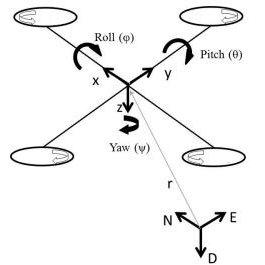

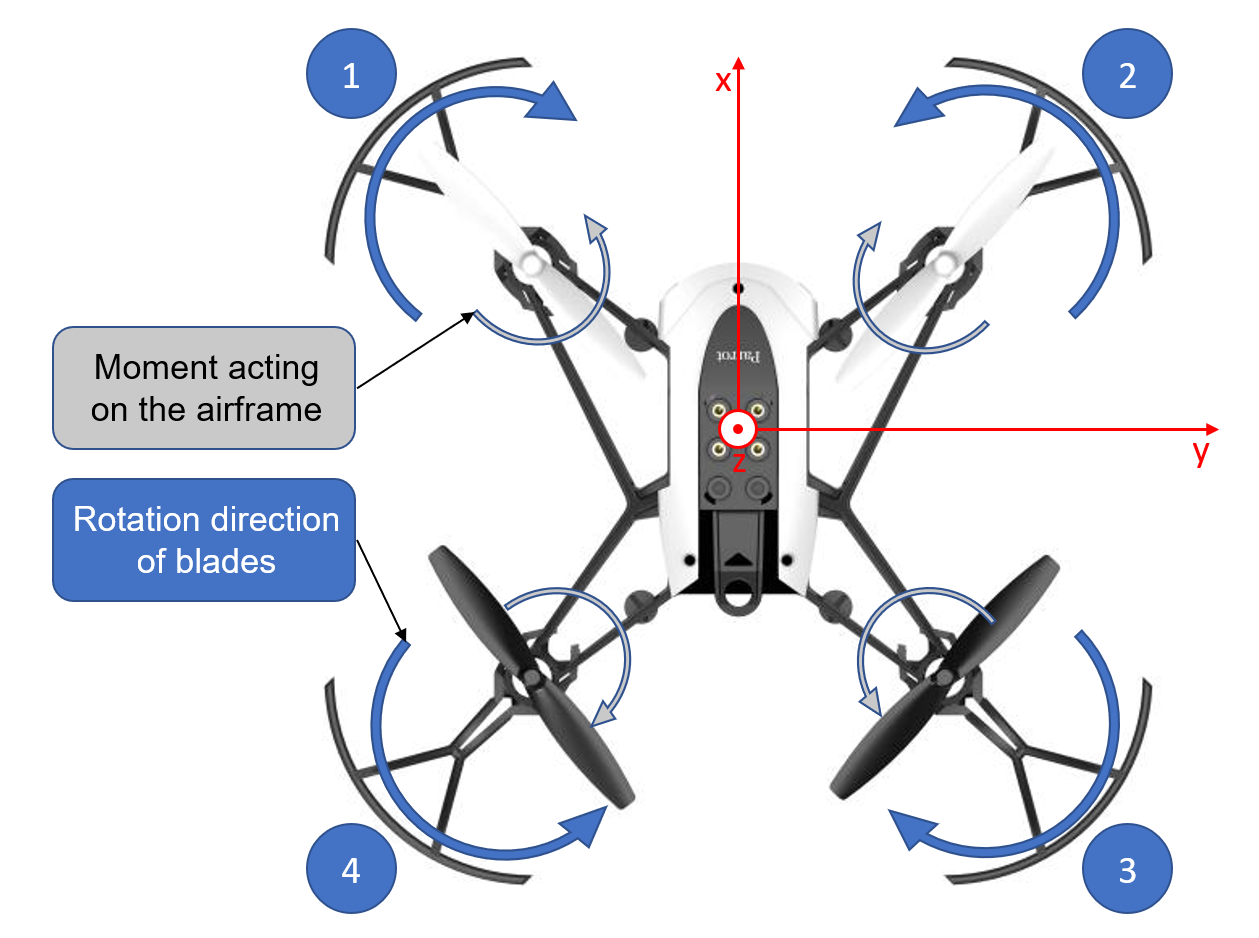

The Symbolic Toolbox is a perfect tool to derive the state equations and save them as MATLAB Functions. First, let's declare the symbolic variables for states, inputs (MVs) and parameters.

% Clear the variables from the workspace
clear;
% Set this variable to false if generating figures for evaluation purposes.
% Set as true otherwise.
req_input = false;
% Suppress warnings related to deprecated environment block
warning('off','Simulink:VariantAdvisorChecks:ObsoleteSlEnvironmentControllerBlockCauseWithArg')
%% Create real symbolic variables for states, inputs, MVs and parameters
syms input_1 input_2 input_3 input_4 Ixx Iyy Izz k l m b g real
syms x y z phi theta psi vx vy vz p q r real

where:

**States **

$x$: x position in global coordinates [m]

$y$: y position in global coordinates [m]

$z$: z position in global coordinates [m]

$\phi$ (phi): roll angle [rad]

$\theta$ (theta): pitch angle [rad]

$\psi$ (psi): yaw angle [rad]

$$v_x$
$: x velocity in inertial frame of reference [m/s]

$$v_y$
$: y velocity in inertial frame of refenence [m/s]

$$v_z$$: z velocity in inertial frame of reference [m/s]

$p$: angular velocity around x axis of body coordinate system [rad/s]

$q$: angular velocity around y axis of body coordinate system [rad/s]

$r$: angular velocity around z axis of body coordinate system [rad/s]

**Control Inputs**

$$T_i$$: Thrust produced by rotor $$i$$ along the [0;0;1] axis [N] ($$-$ve$ is upwards).

**Parameters**

$g$: gravitational acceleration [m/s^2]

$b$: rotor drag constant [kg*m^2]

$k$: rotor lift constant [kg*m]

$l$: moment arm between rotor and centre of mass [m]

$I_{ii}$ (Iii): diagonal elements of inertia matrix [kg*m^2]

For the Parrot Mambo, the parameters are:

load UAV_NominalParameters % Make sure this is in your path
%IxxVal  %Units kg * m^2
%IyyVal  %Units kg * m^2
%IzzVal  %Units kg * m^2
%kVal  %Units N * s^2 = kg * m
%lVal  %Units m
%mVal  %Units kg
%bVal  %Units N * m * s^2= kg * m^2

paramValues =     0.0001    0.0001    0.0001    0.0000    0.0441    0.0630    0.0000    9.8100


gVal = 9.81; %Units kg * m / s^2

paramValues = [IxxVal IyyVal IzzVal kVal lVal mVal bVal gVal]

During the flight, the quadcopter's coordinate system will be rotating. Therefore, we need to relate it to the global coordinates using a rotational matrix

%R-ZYX Euler

$$Rz = \left(\begin{array}{ccc} \cos\left(\psi \right) & -\sin\left(\psi \right) & 0\\ \sin\left(\psi \right) & \cos\left(\psi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Rz = [cos(psi), -sin(psi), 0;
    sin(psi), cos(psi), 0;
    0, 0, 1]

$$Ry = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

Ry = [cos(theta), 0, sin(theta);
    0, 1, 0;
    -sin(theta), 0, cos(theta)]

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$

Rx = [1, 0, 0;
    0, cos(phi), -sin(phi);
    0, sin(phi), cos(phi)]

$$R\_Euler = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$


% Rotation matrix from body frame to inertial frame
R_Euler = Rz*Ry*Rx

Recall that our input for motor $i$ is simply the thrust $$$T_i$$$ which it generates. Therefore, the total thrust generated is 

% Thrust force
Fz = (input_1 + input_2 + input_3 + input_4);

The produced thrust also generates moments around the x and y-axis:


$$$$L_i=\pm l \cdot T_i$$$$



$$$$M_i=\pm l \cdot T_i$$$$


where $L$ and $M$ are moments acting on the x and y-axis respectively and $l$ is the moment arm of the thrust. Due to symmetry of the drone the $l$ value is the same for both axes.

The thrust generated by a single rotor can be estimated as


$$-\frac{1}{2} \rho c_T V_{tip,i}^2 \cdot A_{ref}=-\frac{1}{2} \rho c_T R^2 \cdot A_{ref} \cdot \omega^2_i=-k \cdot  \omega^2_i$$


where $c_T$ is a coefficient related to the blade geometry, $A_{ref}$ is the rotor disk area, $V_{tip}$ is the velocity of the blade's tip and $R$ is the radius of the rotor. Since all the variables except $\omega^2$ are constant, they can be substituted with a single coefficient $k$. 

Additionaly, the drag created at the blades needs to be counteracted by motor torque:


$$$N_i = \frac{\pm R \cdot Drag}{2} = \pm \frac{R}{4} \rho c_D V_{tip,i}^2 \cdot A_{ref}= \pm \frac{1}{4} \rho c_D R^3 \cdot A_{ref} \cdot \omega_i^2 = \pm b \cdot \omega^2_i = \pm \frac{b}{k} \cdot T_i $$$


where $c_D$ is the drag coefficient related to the blade geometry. Where all of the constant variables except for $$F_{z_i}}$$  and $k$ are substituted by a single parameter $b$. Therefore, the total moments acting on the vehicle are:

% Moments
L = l * (- input_1 + input_2 + input_3 - input_4);
M = l * (- input_1 - input_2 + input_3 + input_4);
N = (b ./ k) * (input_1 - input_2 + input_3 - input_4);

Note the positive moments are defined by the right-hand rule. 

Having defined the forces and moments acting on the system and the rotation matrix, we can start deriving equations of motion. Firstly, the rate of change of the global frame positions is simply the velocity vector in the global frame of reference:

% Position in global frame of reference
f(1:3) = [vx; vy; vz];

The Euler angles rates are

% Euler angles rates
f(4) = p + (q * sin(phi) + r * cos(phi)) * tan(theta);
f(5) = q * cos(phi) - r * sin(phi);
f(6) = (q * sin(phi) + r * cos(phi)) / cos(theta);

The linear acceleration of the system is obtained from Newton's Second Law, with the thrust vector rotated to the inertial frame:

% Acceleration in inertial frame
f(7:9) = R_Euler*[0;0;Fz]/m + [0;0;g];

Using the vector transport theorem, the angular acceleration of the system can be defined as

% Rotational Acceleration
f(10) = (L + (Iyy - Izz) * q * r) / Ixx;
f(11) = (M + (Izz - Ixx) * p * r) / Iyy;
f(12) = (N + (Ixx - Iyy) * p * q) / Izz;

Use MATLAB [subs](https://www.mathworks.com/help/symbolic/subs.html) function to replace the parameter variables with their respective values and [simplify](https://www.mathworks.com/help/symbolic/simplify.html) the result:

% Replace parameters
f = subs(f, [Ixx Iyy Izz k l m b g], paramValues);      
f = simplify(f);                                        

Let us now group the states and normalised control inputs:

% Group symbolic variables
state = [x y z phi theta psi vx vy vz p q r];
control = [input_1, input_2, input_3, input_4];

$$B = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2}\\ \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1}\\ \sigma_{3} & \sigma_{3} & \sigma_{3} & \sigma_{3}\\ -756.5620 & 756.5620 & 756.5620 & -756.5620\\ -615.1486 & -615.1486 & 615.1486 & 615.1486\\ 20.3862 & -20.3862 & 20.3862 & -20.3862 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=15.8730\,\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-15.8730\,\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ \sigma_{2}=15.8730\,\sin\left(\varphi \right)\,\sin\left(\psi \right)+15.8730\,\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{3}=15.8730\,\cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}$$

Having now defined the state equations, obtain their Jacobians using [jacobian](https://www.mathworks.com/help/symbolic/sym.jacobian.html)

% Calculate linearization
A = jacobian(f,state)
B = jacobian(f,control)

input_Eq =    -0.1545   -0.1545   -0.1545   -0.1545


We can also find the motor speeds required to achieve equilibrium at given coordinates. 

To maintain stable position and orientation, all velocities need to be zero. This also means the pitch and yaw angle need to be zero as well.

Finally, look at the state equations and answer the following question: Does the position of the drone affect equilibrium? What would be the most convenient point to linearise at?

As an example, one can compute the equilibrium input when the states are all zero using MATLAB functions [subs](https://www.mathworks.com/help/symbolic/subs.html) and [solve](https://www.mathworks.com/help/symbolic/solve.html):

f_StatesZero = subs(f, state, zeros(1,12));                       
[input_Eq1, input_Eq2, input_Eq3, input_Eq4] = solve(f_StatesZero == 0, control);     
input_Eq = double([input_Eq1 input_Eq2 input_Eq3 input_Eq4])               
%Save the result in a mat file
save('Equilibrium inputs', 'input_Eq')

## Ensure that the Dependencies for the Parrot Model are Installed Properly

Before continuing, it is important to ensure that all of the dependencies for the parrot model are installed. Please make sure that [Simulink](https://uk.mathworks.com/products/simulink.html), the [Aerospace Toolbox](https://uk.mathworks.com/products/aerospace-toolbox.html?requestedDomain=), [Aerospace Blockset](https://uk.mathworks.com/products/aerospace-blockset.html?requestedDomain=), the [Signal Processing Toolbox](https://uk.mathworks.com/products/signal.html), and the [Simulink Design Optimization Toolbox](https://uk.mathworks.com/products/sl-design-optimization.html) are all installed on your machine. Note that when installing the Parrot add-on you might be asked to setup the Parrot hardware and connect the drone to your computer - this is not necessary for you to run this script, so you can skip this step when asked.

The code below verifies that everything you need to run the model is properly set up.

ver_info = struct2array(ver);
simulink_installed = contains(ver_info, 'Simulink')
aero_installed = contains(ver_info, 'Aerospace Toolbox')
aero_block_installed = contains(ver_info, 'Aerospace Blockset')
signal_installed = contains(ver_info, 'Signal Processing Toolbox')
design_installed = contains(ver_info, 'Simulink Design Optimization')
if simulink_installed && aero_installed && aero_block_installed && signal_installed && design_installed
    disp('All dependencies are met.')
else
    error('Missing model dependencies. Ensure that all of the requirements are properly installed before proceeding.')
end

Additionally, ensure that you are running Simulink R2024b or newer. Note that you should be able to run this script in MATLAB Online if you wish.

## Examine the Existing PID Controller

In order to familiarize yourself with the Parrot environment, begin by examining the default PID controller used by the simulation environment. 

Note that the controller is a discrete-time PID controller. The sample period `Ts` can be found in `utilities/startVars.m`

Why do you think the controller is organized as seen? Why is the x and y position control linked to attitude control, while altitude control is mostly decoupled? Whenever you are done examining the controller, press 'Enter' to continue.

if req_input
open_system('PID/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to start PID simulation')
end

Next, try running the simulation and examine how it performs.

if req_input
close_system('flightControlSystem');
end
pidProj = openProject('PID/HoverWithPID.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(1)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,1),'k--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,2),'r--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(2)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,4),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,5),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,6),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,1,:)),'k')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,2,:)),'r')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,3,:)),'b')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,4,:)),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
if req_input
input('Press "Enter" key to move on to testing PID robustness')
end

To examine the robustness of the controller to different model parameters, we use the Simulink Response Optimizer with scenarios considering mass variations of ±5 grams and variations in the real thrust produced of ±10%.   

if req_input
load('robustness_mass_thrust.mat')
sdotool(SDOSessionData)
end

Press the "Plot Model Response" button to run the simulation under the different scenarios and examine the trajectories generated for the x, y, and z positions. This may take several minutes, as a complete simulation run is required for each of the scenarios considered.  As you can see, the performance of x and y position tracking is almost unaffected by the uncertainties, while z position tracking degrades under certain scenarios. A guide to using the Response Optimizer can be found [here](https://uk.mathworks.com/help/sldo/response-optimization.html?s_tid=CRUX_lftnav).

Additional uncertain variables can be included in the robustness analysis by modifying the `UncVar` object. Check the `Vehicle` object for a list of drone properties that can be modified. Note, however, that the number of scenarios required scales exponentially with the number of uncertain variables considered, so expect the simulation to take a long while if you examine more than two or three quantities at once. 

Once done, press 'Enter' again to move on to the next section.

if req_input
input('Press the "Enter" key to continue on to LQR controller design')
end
close(pidProj)

## Design an LQR Controller for Position Control

Using the equations of motion derived above, design an LQR controller for position and yaw control of the quadrotor vehicle. The reference your controller will recieve consists of the desired position and yaw, augmented with zeros for all of the other states. Show how you obtain the gains you choose to use. Define your desired output through a $$C$$ matrix and use that in trying to obtain your controller gains $K$. 

**Note:** When you run the following sections, consider that we have used a discrete-time state-space block in simulink to act as an LQR controller. The input to this state-space block ($$\mathbf{u}_k$$) is the error between your reference and estimated state, and the output of this state-space block ($$\mathbf{y}_k$$) should be your LQR control input i.e $\mathbf{y}_k$ $=$ $-K \mathbf{u}_k$ for some gain matrix $K$. Although this may seem confusing at first, the formulation comes in handy when incorporating integral action in the later sections. 

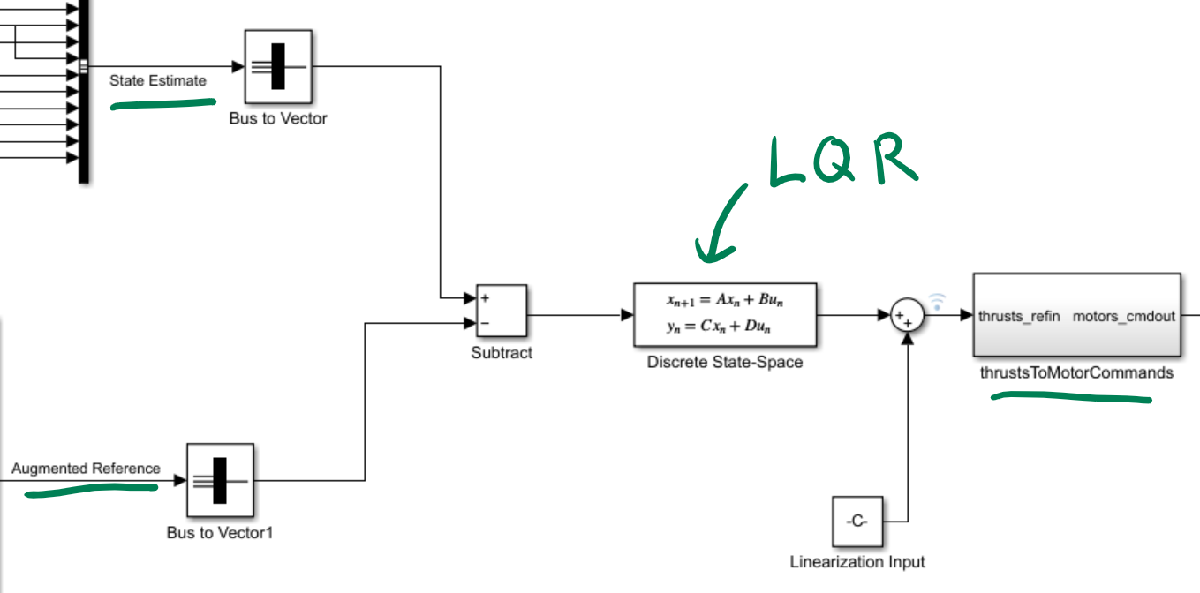

% obtain linearised system: A B C D matrices evaluated at equilibrium
y = [x;y;z;psi];
C = jacobian(y, state);
D = jacobian(y, control);
A_eq = double(subs(A, [state control], {0 0 0 0 0 0 0 0 0 0 0 0 -0.1545 -0.1545 -0.1545 -0.1545}));
B_eq = double(subs(B, [state control], {0 0 0 0 0 0 0 0 0 0 0 0 -0.1545 -0.1545 -0.1545 -0.1545}));
C_eq = double(subs(C, [state control], {0 0 0 0 0 0 0 0 0 0 0 0 -0.1545 -0.1545 -0.1545 -0.1545}));
D_eq = double(subs(D, [state control], {0 0 0 0 0 0 0 0 0 0 0 0 -0.1545 -0.1545 -0.1545 -0.1545}));

% define Q R for solving the cost function 
Q = zeros(12); Q(1,1) = 1; Q(2,2) = 1; Q(3,3) = 100; Q(6,6) = 1;
R = zeros(4); R([1 6 11 16]) = 2;

% use LQR to solve for the feedback gain K
[K, ~, ~] = lqr(ss(A_eq,B_eq,C_eq,D_eq),0.01*Q,3*R);


Next, transfer the gains you have computed to the state-space block in the simulink model for the controller. Note that the controller operates in discrete time, so your design will have to be discretized. Additionally, consider the fact that the input to your state-space block ($$\mathbf{u}_k$$) is the error between your reference and estimated state.

%{
if req_input
open_system('LQR/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" key to start LQR simulation')
end

Then, run the simulation until you are satisfied with the performance of the system.

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(3)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,1),'k--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,2),'r--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(4)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,4),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,5),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,6),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,1,:)),'k')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,2,:)),'r')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,3,:)),'b')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,4,:)),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
if req_input
input('Press "Enter" key to proceed to robust LQR testing')
end
%}

Once you're done, press 'Enter' again to move on to the next section.

## Test the Robustness of your LQR Position Controller

The LQR controller you previously designed assumed perfect information about the quadrotor properties. When deploying code onto real hardware, model mismatch will often lead to a degradation in overall performance. To illustrate this, we consider the same scenarios for the mass and propeller thrust constant as for the PID controller

%{
if req_input
load('robustness_mass_thrust.mat')
sdotool(SDOSessionData)
end

By pressing the "Plot Model Response" button, you can examine the x, y, and z position response to the different scenarios.  Once again, feel free to add additional uncertain variables for your simulation to consider, or to modify the values given in the example. Note that the choice of uncertainty values included by default is simply a suggestion, and you are free to design your controller to be robust to a larger or smaller range of uncertainties. 

In the code box below, you can design new gains that improve on the robustness of your controller. What changes to the closed-loop eigenvalues do you think are likely to lead to safer overall behaviour?

Please note that you are allowed to use the response optimizer or any other tool to help you in designing your gains, but no support will be provided to help you do so.

Press 'Enter' once you are ready to procede to the next section.

if req_input
input('Press "Enter" to move on to velocity control')
end
close(lqrProj)
%}

## Design an LQR Controller for Velocity Control

Now, repeat the LQR design process but for velocity and yaw tracking instead of position control. The reference your controller will receive consists of the desired velocity and yaw, augmented with zeros for all of the other states. If you attempt to design the controller as for the position control case, you will run into issues in computing your LQR gains because $$\left(A,Q^{1/2}\right)$$ is not detectable. 

Does the position error have any effect on the velocity tracking dynamics? What about attitude and angular velocity? Think about which subsystem of the full dynamics the controller should actually be designed for, and what the gains for the remainder of the system should be set to. Show how you obtain your gains in the code box below.

## QR tuning methodology:

There are initially 8 variables (psi vx vy vz u1 u2 u3 u4). Since the motion of the drone is axis-symmetric, we deduct that the weighting given to [vx vy] must be the same, [u1 u2 u3 u4] must be the same, hence the number of variables are reduced to 4. Since the solution to cost function depends on the relative weighting, instead of tuning each Q values, we focus on the ratio between two values and define a base magnitude.  We use rms error between reference signal and true signal as a mesure of peroformance.

- With ratios of [0.1, 1, 10], we first study all possible combinations. This is to get a basic understanding of the effect of changing each ratio and the combined effect and link them to the actual physics. The results will instruct us on how to conduct educated tuning next. 

- Use the optimised combo found in step 1 as the starting point for tuning

- tune....

Conclusion / Observation: 

### Step 1

y = [psi;vx;vy;vz];
C = jacobian(y, state);
D = jacobian(y, control);
A_eq = double(subs(A, [state control], {0 0 0 0 0 0 0 0 0 0 0 0 -0.1545 -0.1545 -0.1545 -0.1545}));
B_eq = double(subs(B, [state control], {0 0 0 0 0 0 0 0 0 0 0 0 -0.1545 -0.1545 -0.1545 -0.1545}));
C_eq = double(subs(C, [state control], {0 0 0 0 0 0 0 0 0 0 0 0 -0.1545 -0.1545 -0.1545 -0.1545}));
D_eq = double(subs(D, [state control], {0 0 0 0 0 0 0 0 0 0 0 0 -0.1545 -0.1545 -0.1545 -0.1545}));

% define reduced linearsed drone dynamics to eliminate xyz position
A_eq_reduced = A_eq(4:end, 4:end);
B_eq_reduced = B_eq(4:end, :);
C_eq_reduced = C_eq(4:end, 4:end);


% define Q R for solving cost function
Q_base = [0.1 1 10]; % base magnitude for Q
Q_psi2velxy = [0.1 1 10]; % ratio between Q_psi and Q_velxy, x and y should have same weighting
Q_velz2velxy = [0.1 1 10]; % ratio between Q_velz and Q_velxy
R_base2Q_base = [1 10 100]; % base magnitude for R, all four motors should have same weighting
num1 = length(Q_base); num2 = length(Q_psi2velxy); num3 = length(Q_velz2velxy); num4 = length(R_base2Q_base);
num_combo = num1*num2*num3*num4

num_combo = 81


% run simulation with different K gains
lqrProj = openProject('LQR_vel/HoverWithLQR.prj');

simParams.StartTime = "0";
simParams.StopTime = "65";
cmds = load("mainModels/cmdData.mat");
error_rms = zeros(num_combo,3);


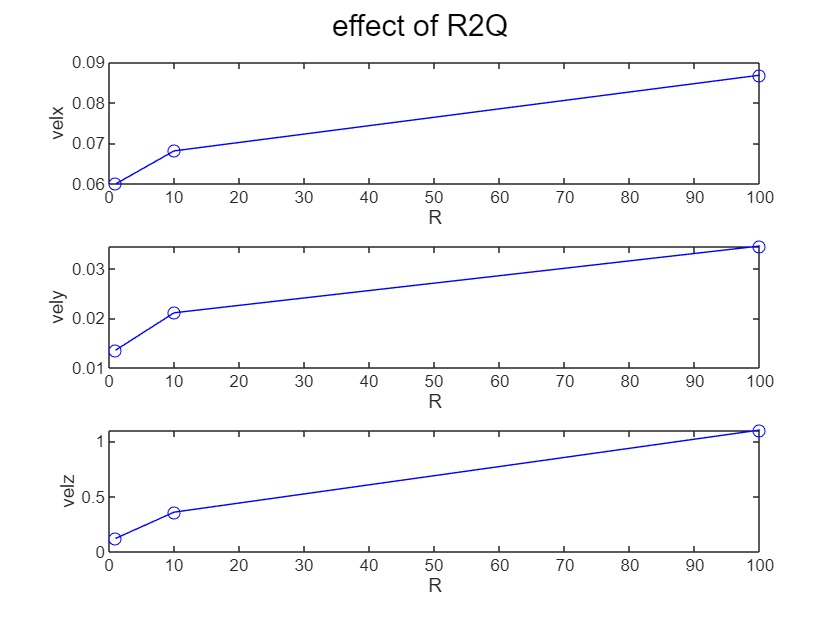

load("error_rms.mat");

% plot
% use sub2ind to extract data, notice the subscript indexing follows (i4,1,i3,i2,i1)
% effect of R2Q
figure
sgtitle('effect of R2Q') 
subplot(3,1,1); plot(R_base2Q_base , error_rms(sub2ind([num4,1,num3,num2,num1],1:num4,1,1,1,1) , 1), 'bo-'); 
xlabel('R'); ylabel('velx');
subplot(3,1,2); plot(R_base2Q_base , error_rms(sub2ind([num4,1,num3,num2,num1],1:num4,1,1,1,1) , 2), 'bo-'); 
xlabel('R'); ylabel('vely');
subplot(3,1,3); plot(R_base2Q_base , error_rms(sub2ind([num4,1,num3,num2,num1],1:num4,1,1,1,1) , 3), 'bo-'); 
xlabel('R'); ylabel('velz');
%set(gca, 'XScale', 'log');

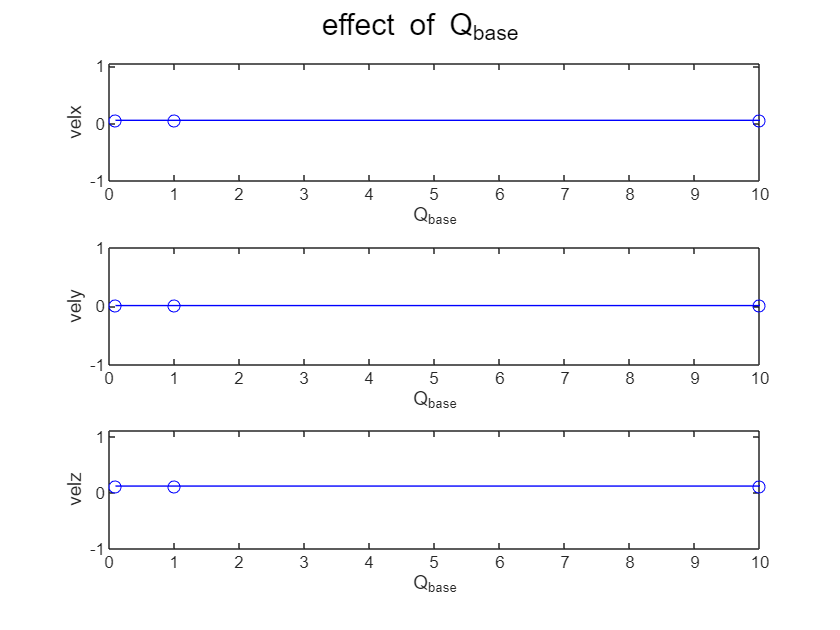



% effect of Q_base
figure
sgtitle('effect of Q_{base}')
subplot(3,1,1); plot(Q_base , error_rms(sub2ind([num4,1,num3,num2,num1],1,1,1,1,1:num1) , 1), 'bo-'); 
xlabel('Q_{base}'); ylabel('velx');
subplot(3,1,2); plot(Q_base , error_rms(sub2ind([num4,1,num3,num2,num1],1,1,1,1,1:num1) , 2), 'bo-'); 
xlabel('Q_{base}'); ylabel('vely');
subplot(3,1,3); plot(Q_base , error_rms(sub2ind([num4,1,num3,num2,num1],1,1,1,1,1:num1) , 3), 'bo-'); 
xlabel('Q_{base}'); ylabel('velz');


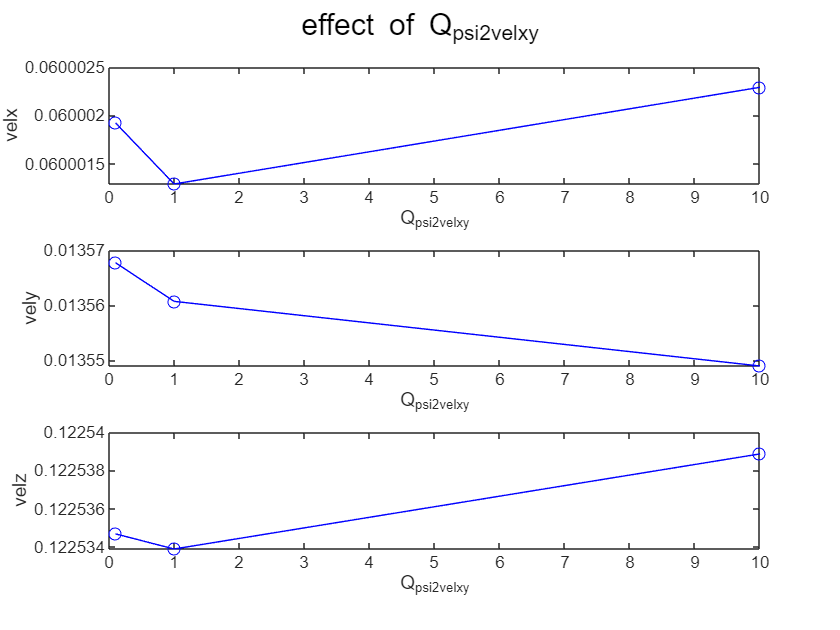

% effect of Q_psi2velxy
figure 
sgtitle('effect of Q_{psi2velxy}')
subplot(3,1,1); plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],1,1,1,1:num2,1) , 1), 'bo-'); 
xlabel('Q_{psi2velxy}'); ylabel('velx'); 
subplot(3,1,2); plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],1,1,1,1:num2,1) , 2), 'bo-'); 
xlabel('Q_{psi2velxy}'); ylabel('vely');
subplot(3,1,3); plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],1,1,1,1:num2,1) , 3), 'bo-'); 
xlabel('Q_{psi2velxy}'); ylabel('velz');


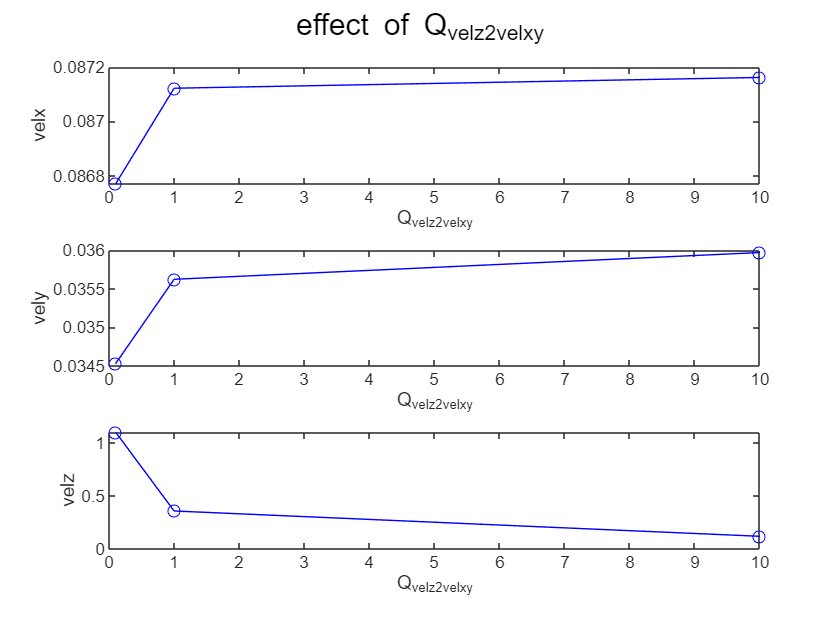

% effect of Q_velz2velxy
figure
sgtitle('effect of Q_{velz2velxy}')
subplot(3,1,1); plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 1), 'bo-'); 
xlabel('Q_{velz2velxy}'); ylabel('velx');
subplot(3,1,2); plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 2), 'bo-'); 
xlabel('Q_{velz2velxy}'); ylabel('vely');
subplot(3,1,3); plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 3), 'bo-'); 
xlabel('Q_{velz2velxy}'); ylabel('velz');


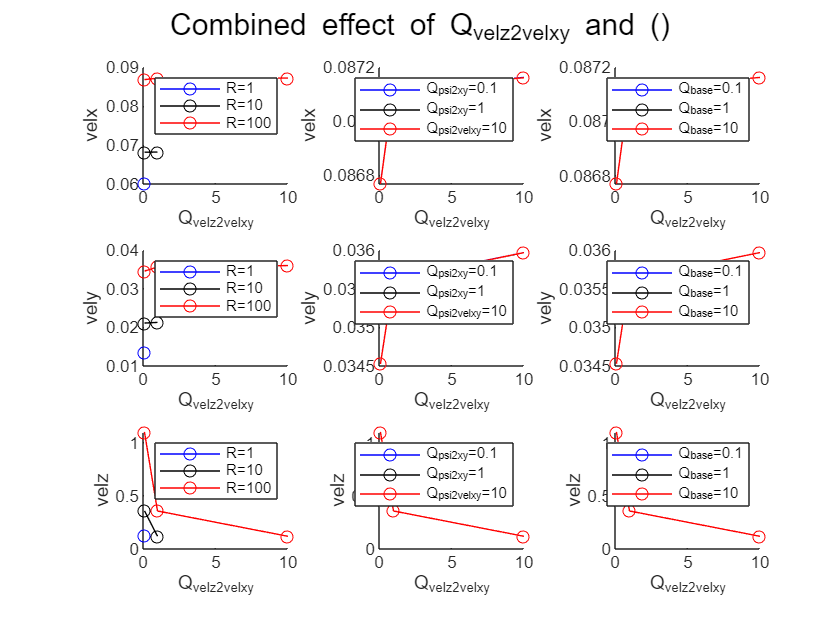

% Combined effect of Q_velz2velxy + sth
figure
hold on
sgtitle('Combined effect of Q_{velz2velxy} and ()')
% velx
% vary R
subplot(3,3,1); 
hold on
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],1,1,1:num3,1,1) , 1), 'bo-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],2,1,1:num3,1,1) , 1), 'ko-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 1), 'ro-'); 
xlabel('Q_{velz2velxy}'); ylabel('velx'); legend('R=1', 'R=10', 'R=100');
hold off
% vary Q_psi2velxy
subplot(3,3,2); 
hold on
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 1), 'bo-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,2,1) , 1), 'ko-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,3,1) , 1), 'ro-'); 
xlabel('Q_{velz2velxy}'); ylabel('velx'); legend('Q_{psi2xy}=0.1', 'Q_{psi2xy}=1', 'Q_{psi2velxy}=10');
hold off
% vary Q_base
subplot(3,3,3); 
hold on
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 1), 'bo-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,2) , 1), 'ko-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,3) , 1), 'ro-'); 
xlabel('Q_{velz2velxy}'); ylabel('velx'); legend('Q_{base}=0.1', 'Q_{base}=1', 'Q_{base}=10');
hold off

% vely
% vary R
subplot(3,3,4); 
hold on
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],1,1,1:num3,1,1) , 2), 'bo-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],2,1,1:num3,1,1) , 2), 'ko-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 2), 'ro-'); 
xlabel('Q_{velz2velxy}'); ylabel('vely'); legend('R=1', 'R=10', 'R=100');
hold off
% vary Q_psi2velxy
subplot(3,3,5); 
hold on
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 2), 'bo-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,2,1) , 2), 'ko-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,3,1) , 2), 'ro-'); 
xlabel('Q_{velz2velxy}'); ylabel('vely'); legend('Q_{psi2xy}=0.1', 'Q_{psi2xy}=1', 'Q_{psi2velxy}=10');
hold off
% vary Q_base
subplot(3,3,6); 
hold on
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 2), 'bo-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,2) , 2), 'ko-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,3) , 2), 'ro-'); 
xlabel('Q_{velz2velxy}'); ylabel('vely'); legend('Q_{base}=0.1', 'Q_{base}=1', 'Q_{base}=10');
hold off

% velz
% vary R
subplot(3,3,7); 
hold on
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],1,1,1:num3,1,1) , 3), 'bo-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],2,1,1:num3,1,1) , 3), 'ko-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 3), 'ro-'); 
xlabel('Q_{velz2velxy}'); ylabel('velz'); legend('R=1', 'R=10', 'R=100');
hold off
% vary Q_psi2velxy
subplot(3,3,8); 
hold on
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 3), 'bo-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,2,1) , 3), 'ko-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,3,1) , 3), 'ro-'); 
xlabel('Q_{velz2velxy}'); ylabel('velz'); legend('Q_{psi2xy}=0.1', 'Q_{psi2xy}=1', 'Q_{psi2velxy}=10');
hold off
% vary Q_base
subplot(3,3,9); 
hold on
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,1) , 3), 'bo-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,2) , 3), 'ko-'); 
plot(Q_psi2velxy , error_rms(sub2ind([num4,1,num3,num2,num1],3,1,1:num3,1,3) , 3), 'ro-'); 
xlabel('Q_{velz2velxy}'); ylabel('velz'); legend('Q_{base}=0.1', 'Q_{base}=1', 'Q_{base}=10');
hold off

### Step 2

smallest error combo is found, we will use this as starting point

observe that exceeding max thrust occurs only when Q_velz is 1:1 or 10:1 to R, and is irrelevant to the ratio between all others. Therefore we must always keep Q_velz / R <= 1:10

% find smallest error combo
% define overall error as the sum of three errors (so equally weighted)
[error_rms_min, ind] = min(sum(error_rms,2))
[i4,~,i3,i2,i1] = ind2sub([3 1 3 3 3], ind);
QR_min = [Q_base(i1) Q_psi2velxy(i2) Q_velz2velxy(i3) R_base2Q_base(i4)]

error_rms_min = 0.1961

ind = 19

Q_reduced = Q_base(i1) * diag([0 0 Q_psi2velxy(i2) 1 1 Q_velz2velxy(i3) 0 0 0]); 
R = (R_base2Q_base(i4) * Q_base(i1)) * diag([1 1 1 1]);

QR_min =     0.1000   10.0000    0.1000    1.0000


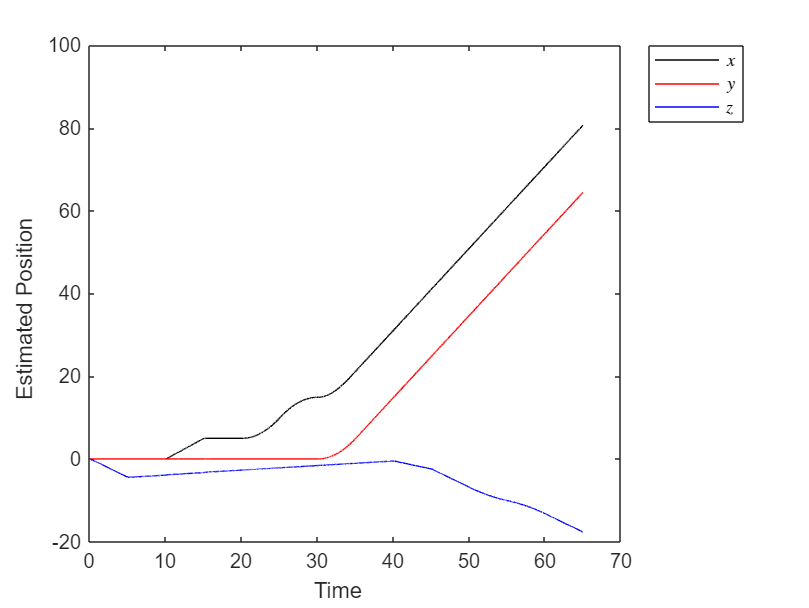

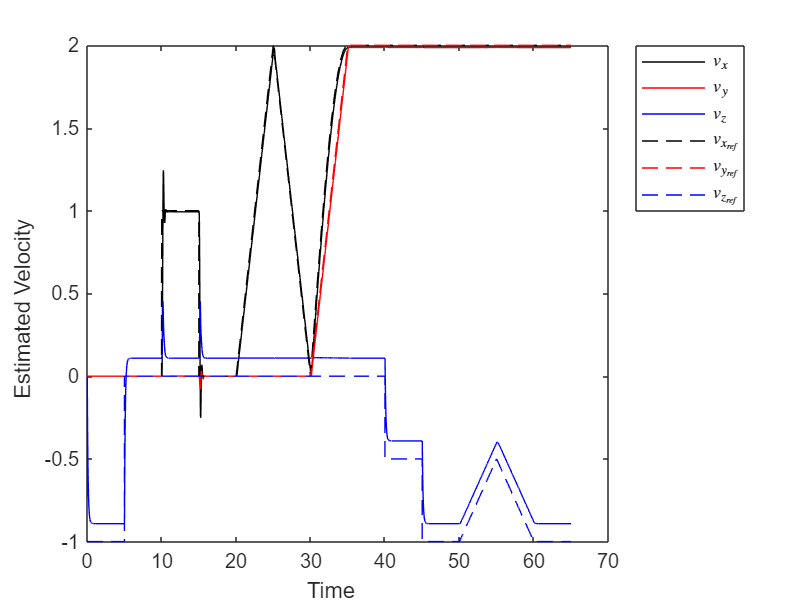

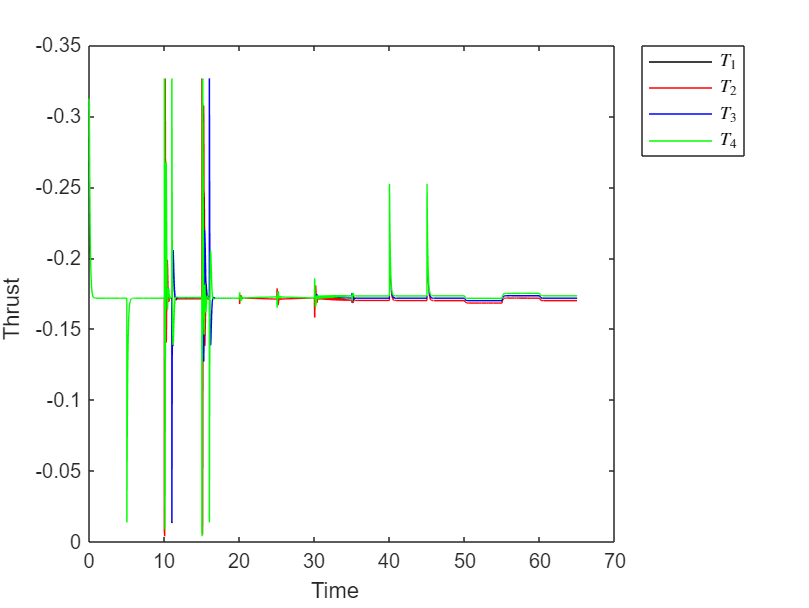

[K_reduced, ~, ~] = lqr(ss(A_eq_reduced,B_eq_reduced,[],[]), Q_reduced, R);
K = [zeros(4,3) , K_reduced];
plot_LQR_vel()

% find out under what cases the max thrust is exceeded

[i4,~,i3,i2,i1] = ind2sub([3 1 3 3 3], find(isnan(error_rms(:,1))));
QR_maxthrust = [Q_base(i1)' Q_psi2velxy(i2)' Q_velz2velxy(i3)' R_base2Q_base(i4)']



QR_maxthrust =     0.1000    0.1000    1.0000    1.0000
    0.1000    0.1000   10.0000    1.0000
    0.1000    0.1000   10.0000   10.0000
    0.1000    1.0000    1.0000    1.0000
    0.1000    1.0000   10.0000    1.0000
    0.1000    1.0000   10.0000   10.0000
    0.1000   10.0000    1.0000    1.0000
    0.1000   10.0000   10.0000    1.0000
    0.1000   10.0000   10.0000   10.0000
    1.0000    0.1000    1.0000    1.0000


### Step 3

Next, transfer the gains to the simulation environment, remembering that they should be discretized

if req_input
open_system('LQR_vel/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" to start the simulation')
end

Once done, press 'Enter' to launch the full simulation model and examine the performance of the controller you designed. Take your time to iterate and achieve a suitable level of performance for the system.  

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_vel/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);

Error using matlab.project.loadProject
The file or folder "LQR_vel/HoverWithLQR.prj" does not exist.

Error in openProject

cmds = load("mainModels/cmdData.mat");
figure(5)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(6)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,4),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,5),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,6),'b')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,1),'k--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,2),'r--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,1,:)),'k')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,2,:)),'r')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,3,:)),'b')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,4,:)),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

if req_input
load('robustness_mass_thrust.mat')
sdotool(SDOSessionData)
input('Press "Enter" to consider LQR for position tracking with integral action')
end

If you are happy with how your controller is doing, you can hit 'Enter' again to move on to the next section 

close(lqrProj)

## Add Integral Action to the LQR Position Controller

When designing the position controller, you may have noticed the existence of a persistent altitude offset. We now attempt to fix this by augmenting the controller with an integral component. Choose the number of states you wish to add to your controller, and design your gains in the code box below.

% define Q R for solving cost function
Q_base = [0.1 1 10]; % base magnitude for Q
Q_psi2xy = [0.1 1 10]; % ratio between Q_psi and Q_velxy, x and y should have same weighting
Q_z2xy = [0.1 1 10]; % ratio between Q_velz and Q_velxy
R_base2Q_base = [1 10 100]; % base magnitude for R, all four motors should have same weighting
Q_basei2Q_base = [0.1 1 10];
Q_psii2xyi = [0.1 1 10];
Q_zi2xyi = [0.1 1 10];

% num1 = length(Q_base); num2 = length(Q_psi2xy); num3 = length(Q_z2vxy); num4 = length(R_base2Q_base);
num_combo = 3^7

% run simulation with different K gains
lqrProj = openProject('LQR_vel/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
cmds = load("mainModels/cmdData.mat");
error_rms = zeros(num_combo,3);


% ITERATION STARTS HERE
for i1 = 1:length(Q_base)
    for i2 = 1:length(Q_psi2velxy)
        for i3 = 1:length(Q_velz2velxy)
            for i4 = 1:length(R_base2Q_base)
                Q_reduced = Q_base(i1) * diag([0 0 Q_psi2velxy(i2) 1 1 Q_velz2velxy(i3) 0 0 0]); 
                R = (R_base2Q_base(i4) * Q_base(i1)) * diag([1 1 1 1]);
                % use LQR to solve for feedback gain
                [K_reduced, ~, ~] = lqr(ss(A_eq_reduced,B_eq_reduced,[],[]), Q_reduced, R);
                K = [zeros(4,3) , K_reduced]; % augment back to the original 12by12 matrix with 0 gains for position, the name K must be consistent with the simulink one !!!!
                
                ind = (i1-1)*num2*num3*num4 + (i2-1)*num3*num4 + (i3-1)*num4 + i4
                
                % if max thrust exceeded, catch the error and continue theiteration
                try 
                    simInfo = sim('parrotMinidroneHover',simParams); 
                    error_rms(ind,:) = rms((cmds.ans.Data(1:13000,1:3) - simInfo.estimatedStates.signals.values(2:end, 4:6)) , 1);
                    clear simInfo
                catch
                    disp('max thrust exceeded')
                    error_rms(ind,:) = NaN; % when max thrust exceeded, set error to NaN
                end
            end
        end
    end
end

A_aug = [A_eq, zeros(size(A_eq,1),size(C_eq,1));...
    C_eq, zeros(size(C_eq,1),size(C_eq,1))];

B_aug = [B_eq; zeros(size(C_eq,1),size(B_eq,2))];
C_aug = [C_eq, zeros(size(C_eq,1),size(C_eq,1));...
    zeros(4,12), eye(4)];
D_aug = D;

Q = zeros(12); Q(1,1) = 1; Q(2,2) = 1; Q(3,3) = 1; Q(6,6) = 0.1;
Q_aug = blkdiag(Q, diag([1 1 1 1]));
R_aug = 100*eye(4,4);
Ts = 0.005;

[K_posint, ~,~] = lqrd(A_aug, B_aug, Q_aug, R_aug, Ts);

Kp_pos = K_posint(:,1:12);
Ki_pos = zeros(4,12);
Ki_pos(:,1:3) = K_posint(:,13:15);
Ki_pos(:,6) =K_posint(:,16);

Error using lqrd (line 86)
Cannot compute the stabilizing Riccati solution S for the LQR design. 
This could be because: 
  * (A,E) has imaginary-axis or unit-circle modes that are not controllable through B, 
  * R is not positive definite, 
  * [Q N;N' R] is indefinite, 
  * The E matrix in the state equation is singular.

Next, transfer your gains to the controller model. Think about how to represent your controller as a state space block where $$\mathbf{u}_k$$ is your reference error.

if req_input
open_system('LQR_integral/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" start the simulation')
end

Then, run the simulation until you are satisfied with the performance of the system. Do you notice a decrease in the steady state error? 

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_integral/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(9)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,1),'k--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,2),'r--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(10)
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,4),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,5),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,6),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,1,:)),'k')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,2,:)),'r')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,3,:)),'b')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,4,:)),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

if req_input
load('robustness_mass_thrust.mat')
sdotool(SDOSessionData)
input('Press "Enter" key to move on to velocity-tracking LQR with integral action')
end

Once you're done, press 'Enter' again to move on to the next section.

close(lqrProj)

## Add Integral Action to the LQR Velocity Controller

Now do this again to add integral action to the LQR velocity controller. As usual, show how you obtain your gains here.

% define Q R for solving cost function
Q_basei2Q_base = [0.1 1 10];
Q_psii2velxyi = [0.1 1 10];
Q_velzi2velxyi = [0.1 1 10];

% num1 = length(Q_base); num2 = length(Q_psi2xy); num3 = length(Q_z2vxy); num4 = length(R_base2Q_base);
num_combo = 3^3;

% define open-loop
C_eq_reduced = C_eq(:,4:end);
A_eq_reduced_aug = [A_eq_reduced, zeros(9,4);...
    C_eq_reduced, zeros(4,4)];
B_eq_reduced_aug = [B_eq(4:end,:);...
    zeros(4,4)];

% run simulation with different K gains

Reference to a cleared variable C_eq.

lqrProj = openProject('LQR_vel_integral/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
cmds = load("mainModels/cmdData.mat");
error_rms = zeros(num_combo,3);


% ITERATION STARTS HERE
for i1 = 1:length(Q_basei2Q_base)
    for i2 = 1:length(Q_psii2velxyi)
        for i3 = 1:length(Q_velzi2velxyi)
                Q_reduced = diag([0 0 1 0.1 0.1 0.01 0 0 0]); 
                Q_reduced_aug = blkdiag(Q_reduced, 0.1*Q_basei2Q_base*diag([Q_psii2Q_xyi 1 1 Q_velzi2Q_velxyi]));
                R = 0.5*diag([1 1 1 1]);

                % use LQR to solve for feedback gain
                [K_reduced_aug, ~, ~] = lqrd(A_eq_reduced_aug,B_eq_reduced_aug, Q_reduced_aug, R, 0.005);
                Kp = [zeros(4,3) , K_reduced_aug(:,1:9)]; % augment back to the original 12by12 matrix with 0 gains for position, the name K must be consistent with the simulink one !!!!
                Ki = zeros(4,12);
                Ki(:,6) = K_reduced_aug(:,10);
                Ki(:,7:9) = K_reduced_aug(:,11:13);  

                ind = (i1-1)*3^2 + (i2-1)*3 + i3
                
                % if max thrust exceeded, catch the error and continue theiteration
                %try 
                    simInfo = sim('parrotMinidroneHover',simParams); 
                    error_rms(ind,:) = rms((cmds.ans.Data(1:13000,1:3) - simInfo.estimatedStates.signals.values(2:end, 4:6)) , 1);
                    clear simInfo
                %catch
                    %disp('max thrust exceeded')
                    %error_rms(ind,:) = NaN; % when max thrust exceeded, set error to NaN
                %end
           
        end
    end
end

Q_reduced = diag([0 0 1 0.1 0.1 0.01 0 0 0]); 
Q_reduced_aug = blkdiag(Q_reduced, diag([1 1 1 1]));
R = 0.1*diag([1 1 1 1]);

% use LQR to solve for feedback gain
[K_reduced_aug, ~, ~] = lqrd(A_eq_reduced_aug,B_eq_reduced_aug, Q_reduced_aug, R, 0.005);
Kp = [zeros(4,3) , K_reduced_aug(:,1:9)]; % augment back to the original 12by12 matrix with 0 gains for position, the name K must be consistent with the simulink one !!!!

B_eq_reduced_aug =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
   15.8730   15.8730   15.8730   15.8730
 -756.5620  756.5620  756.5620 -756.5620
 -615.1486 -615.1486  615.1486  615.1486
   20.3862  -20.3862   20.3862  -20.3862
         0         0         0         0


Ki = zeros(4,12);
Ki(:,6) = K_reduced_aug(:,10);
Ki(:,7:9) = K_reduced_aug(:,11:13);


Next, transfer your gains to the controller model.

req_input = true;
if req_input
open_system('LQR_vel_integral/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" to start the simulation')
end

Once done, press 'Enter' to launch the full simulation model and examine how the addition of the integral term affects the performance of your controller.

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_vel_integral/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);

cmds = load("mainModels/cmdData.mat");
figure(11)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')

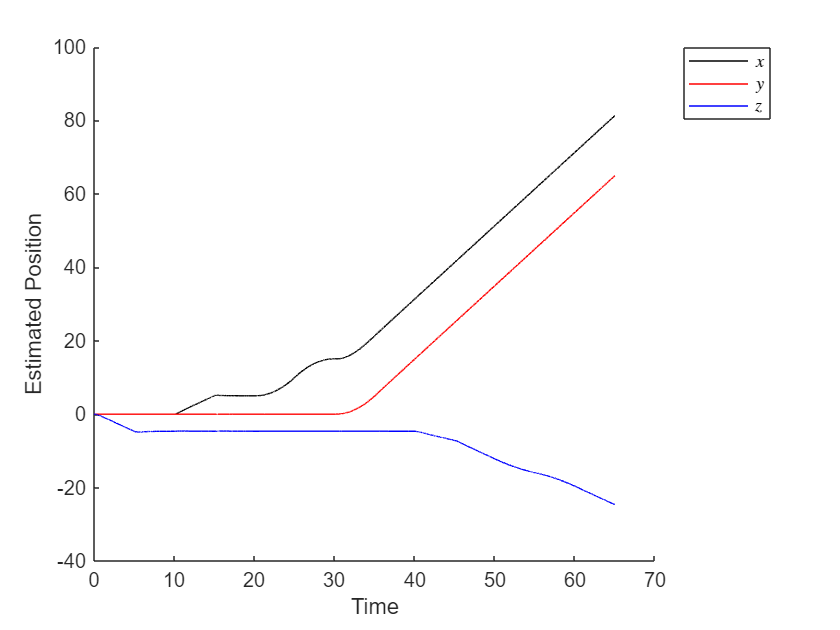

plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(12)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,4),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,5),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,6),'b')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,1),'k--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,2),'r--')

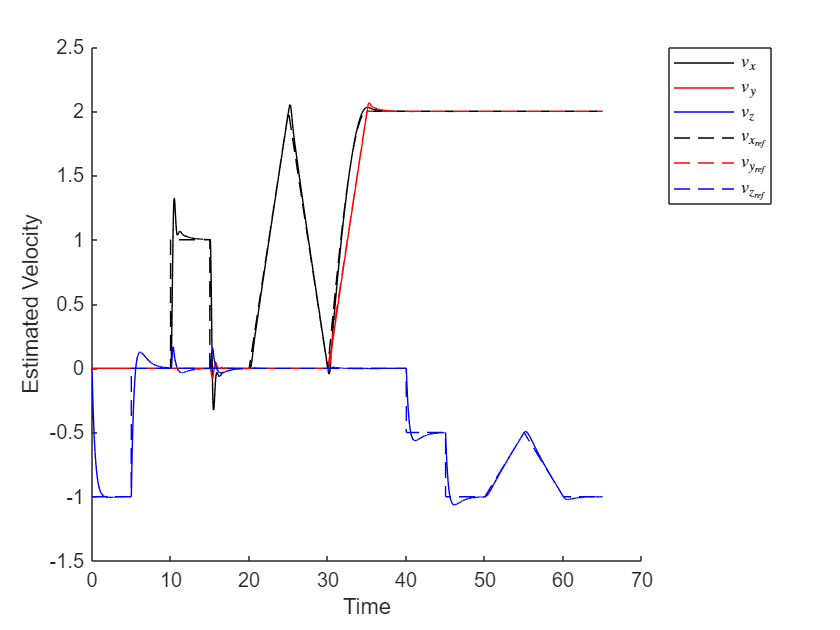

plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,1,:)),'k')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,2,:)),'r')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,3,:)),'b')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,4,:)),'g')

set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

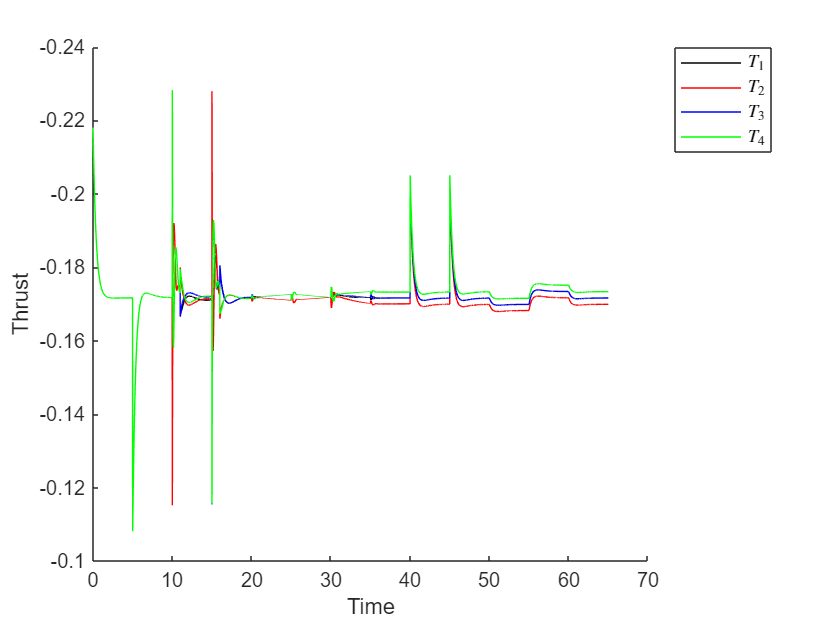

if req_input
load('robustness_mass_thrust.mat')
sdotool(SDOSessionData)
input('Press "Enter" to examine the effects of adding feedforward to LQR for position control')

end

Press 'Enter' again to move on to the next section 

close(lqrProj)

## Add a Feedforward term to the LQR Position Controller with Integral Action

The last modification we consider to attempt improving the performance of the controllers is the addition of a feedforward term to modify the reference, as described in Åström and Murray. Show how you compute your feedforward gain.

Next, transfer your gains to the controller model. Transfer your base LQR and integral gains to the respective blocks, and your feedforward gains to the reference signal gain. Notice the change in control structure from the previous examples to accomodate the added Feedforward term.

if req_input
open_system('LQR_integral_ff/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" to start the simulation')
end

Then, run the simulation until you are satisfied with the performance of the system. How does the performance differ when compared to the base integral case? How is the controller with feedforward different from the previous controllers you designed?

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_integral_ff/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(13)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,1),'k--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,2),'r--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,3),'b--')
legend('$x$','$y$','$z$','$x_{ref}$','$y_{ref}$','$z_{ref}$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(14)
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,4),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,5),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,6),'b')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,1,:)),'k')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,2,:)),'r')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,3,:)),'b')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,4,:)),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

if req_input
load('robustness_mass_thrust.mat')
sdotool(SDOSessionData)
input('Press "Enter" to move on to LQR velocity control with feedforward')
end

Once you're done, press 'Enter' again to move on to the next section.

close(lqrProj)

## Add a Feedforward term to the LQR Velocity Controller with Integral Action

Finally, repeat the design of a feedforward term for the velocity controller. Once again, include both the feedforward and integral terms.

Next, transfer your gains to the controller model. Transfer your base LQR and integral gains to the respective blocks, and your feedforward gains to the matrix multiplying the reference signal.

if req_input
open_system('LQR_vel_integral_ff/controller/flightControlSystem');
open_system('flightControlSystem/Flight Control System/Controller');
input('Press "Enter" to start the simulation')
end

Once done, press 'Enter' to launch the full simulation model and examine the performance of your controller.

if req_input
close_system('flightControlSystem');
end
lqrProj = openProject('LQR_vel_integral_ff/HoverWithLQR.prj');
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");
figure(15)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')
figure(16)
clf
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,4),'k')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,5),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,6),'b')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,1),'k--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,2),'r--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,3),'b--')
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')
figure(3)
clf
ax = axes;
hold on
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,1,:)),'k')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,2,:)),'r')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,3,:)),'b')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,4,:)),'g')
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
if req_input
input('Press "Enter" to proceed to the robustness analysis')
end

As with each of the previous controllers, you can now examine the robustness of your design

if req_input
load('robustness_mass_thrust.mat')
sdotool(SDOSessionData)
input('Press "Enter" to close the project and terminate the script')
end

Press 'Enter' one last time to terminate the simulation.

close(lqrProj)

## FUNCTIONS: 

below are functions created for convenience

function plot_LQR_vel()
simParams.StartTime = "0";
simParams.StopTime = "65";
simInfo = sim('parrotMinidroneHover',simParams);
cmds = load("mainModels/cmdData.mat");

figure
clf
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,1),'k')
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,2),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,3),'b')
hold off
legend('$x$','$y$','$z$','Interpreter','Latex','Location','NorthEastOutside')
xlabel('Time')
ylabel('Estimated Position')

figure
clf
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,4),'k')
hold on
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,5),'r')
plot(simInfo.estimatedStates.time,simInfo.estimatedStates.signals.values(:,6),'b')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,1),'k--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,2),'r--')
plot(cmds.ans.Time(1:13000),cmds.ans.Data(1:13000,3),'b--')
hold off
xlabel('Time')
ylabel('Estimated Velocity')
legend('$v_x$','$v_y$','$v_z$','$v_{x_{ref}}$','$v_{y_{ref}}$','$v_{z_{ref}}$','Interpreter','Latex','Location','NorthEastOutside')

figure
clf
ax = axes;
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,1,:)),'k')
hold on
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,2,:)),'r')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,3,:)),'b')
plot(simInfo.logsout{4}.Values.Time,squeeze(simInfo.logsout{4}.Values.Data(3,4,:)),'g')
hold off
set(ax, 'Ydir', 'reverse')
xlabel('Time')
ylabel('Thrust')
legend('$T_1$','$T_2$','$T_3$','$T_4$','Interpreter','Latex','Location','NorthEastOutside')
end